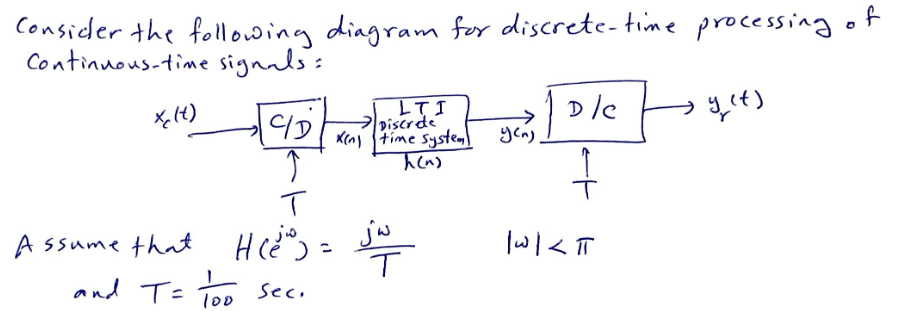

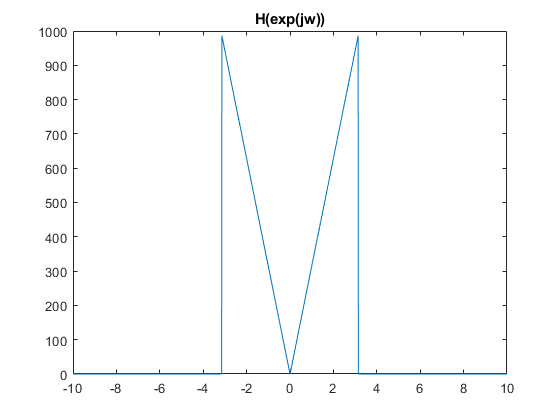

T = 1/100;
w = -10:T:10;

H = DSP_funcs.derivative(w);
plot(w, abs(H))
title("H(exp(jw))")

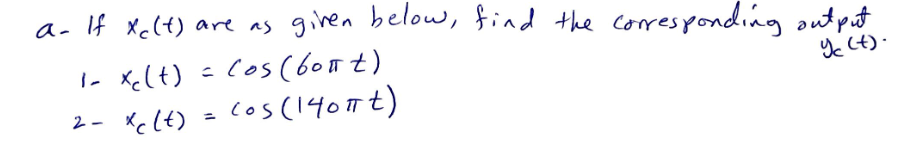

We will begin with cos(60*pi*t)

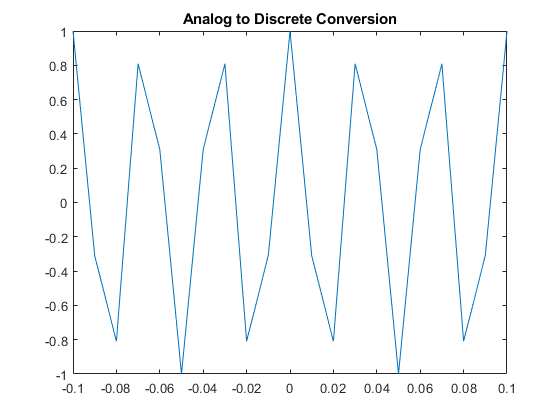

n = -10:T:10;

% Do analog to discrete conversion
x1 = cos(60*pi*n);
plot(n, x1)
xlim([-0.1,0.1])
title("Analog to Discrete Conversion")

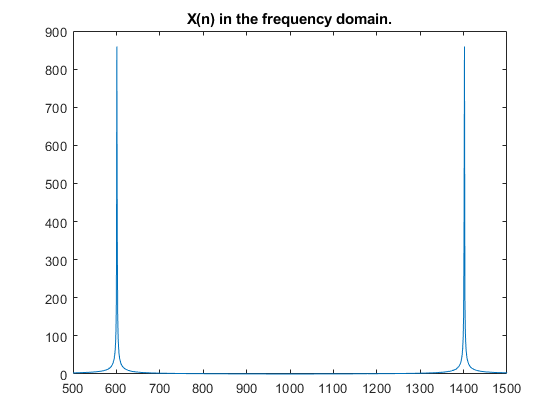


% convolve the input with H
X1 = fft(x1);
plot(abs(X1))
xlim([500,1500])
title("X(n) in the frequency domain.")

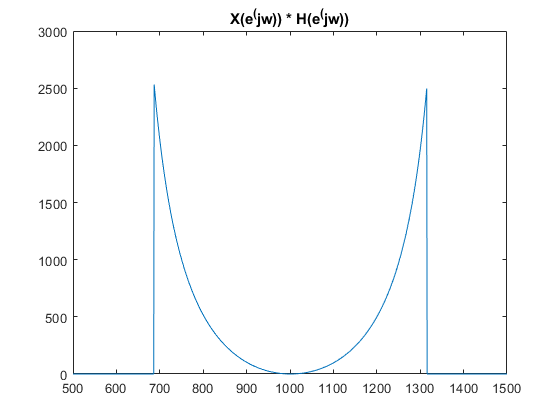

X1H = X1.*H;
plot(abs(X1H))
xlim([500, 1500])
title("X(e^(jw)) * H(e^(jw))")

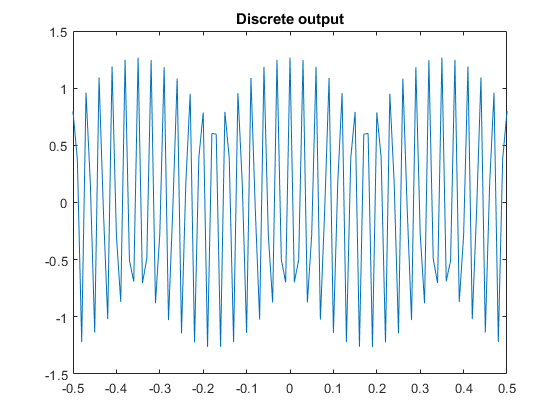


% convert the convolved output back to the discrete time domain
y1n = real(ifft(X1H));
plot(n, y1n)
xlim([-0.5, 0.5])
title("Discrete output")


%resample yr with with sinc interpolation
resample_factor = 10

resample_factor = 10

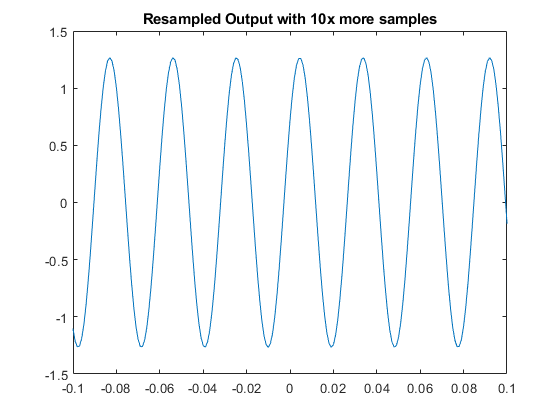

y1r = DSP_funcs.resampleSINC(y1n, resample_factor);
t = -10:T/resample_factor:10 + (resample_factor-1)*T/resample_factor;

plot(t, y1r)
xlim([-0.1, 0.1])
title("Resampled Output with 10x more samples")

Please note a few thigns about yr (the resampled output) versus y1n (the discrete output). With a higher sampling rate of yr, certain effects are no longer seen in the output. Specifically, the sine wave no longer oscillates up and down like there is an additional sine wave added it to it.

Next we will do the same for cos(140*pi*t)

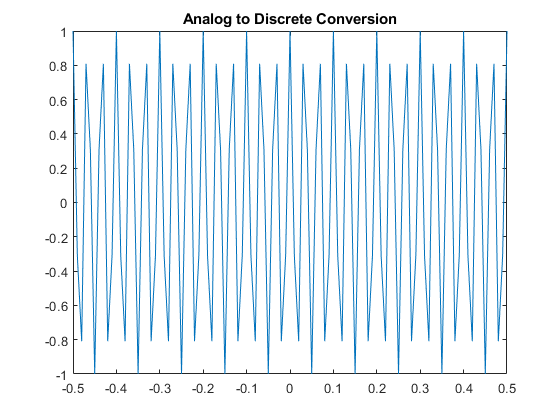

n = -10:T:10;

% Do analog to discrete conversion
x2 = cos(140*pi*n);
plot(n, x2)
xlim([-0.5,0.5])
title("Analog to Discrete Conversion")


% convolve the input with H
X2 = fft(x2);
plot(abs(X2))
xlim([500,1500])
title("X(n) in the frequency domain.")

X2H = X2.*H;
plot(abs(X2H))
xlim([500, 1500])
title("X(e^(jw)) * H(e^(jw))")


% convert the convolved output back to the discrete time domain
y2n = real(ifft(X2H));
plot(n, y2n)
xlim([-0.5, 0.5])
title("Discrete output")


%resample yr with with sinc interpolation
resample_factor = 10

resample_factor = 10

y2r = DSP_funcs.resampleSINC(y2n, resample_factor);
t = -10:T/resample_factor:10 + (resample_factor-1)*T/resample_factor;

plot(t, y2r)
xlim([-0.1, 0.1])
title("Resampled Output with 10x more samples")

The original inputs next to their outputs

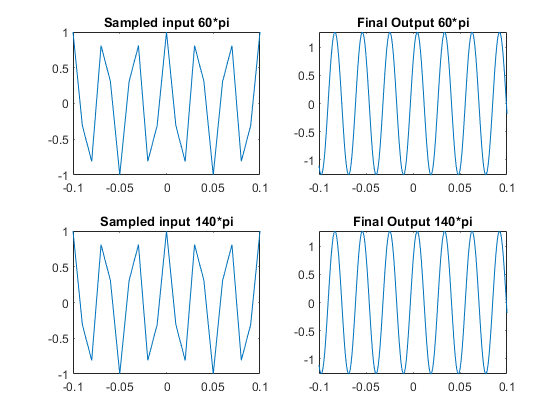

subplot(2,2,1)
plot(n, x1)
title("Sampled input 60*pi")
xlim([-0.1, 0.1])
subplot(2,2,2)
plot(t, y1r)
title("Final Output 60*pi")
xlim([-0.1, 0.1])

subplot(2,2,3)
plot(n, x2)
title("Sampled input 140*pi")
xlim([-0.1, 0.1])
subplot(2,2,4)
plot(t, y2r)
title("Final Output 140*pi")
xlim([-0.1, 0.1])

The output waveform is not what I would expect from a differentiator. Namely, the output should be -sin(t) buti nstead it's sin(t). I believe this issue stems from the fact that our sampling frequency is a little less than twice the frequency of the input signal for x1 and far too low of a sampling frequency for x2. If we were to sample these signals at much higher frequencies, I believe we would see better results for the differentiator. See below for an example.

Tr = 1/1000

Tr = 1.0000e-03

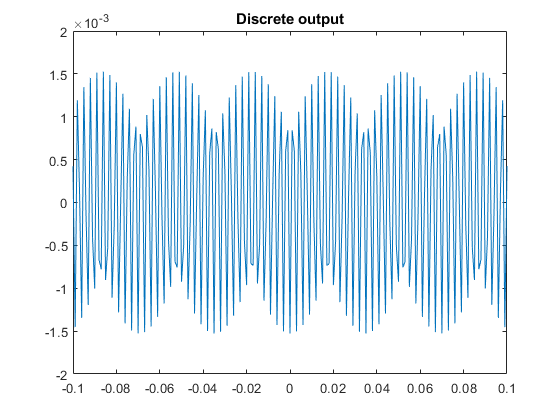

n = -10:Tr:10;
w = -10:Tr:10;
H = DSP_funcs.derivative(w);

% Do analog to discrete conversion
x3 = cos(140*pi*n);

% convolve the input with H
X3 = fft(x3);
X3H = X3.*H;


% convert the convolved output back to the discrete time domain
y3n = real(ifft(X3H));
figure(4)
plot(n, y3n)
xlim([-0.1, 0.1])
title("Discrete output")


%resample yr with with sinc interpolation
resample_factor = 5

resample_factor = 5

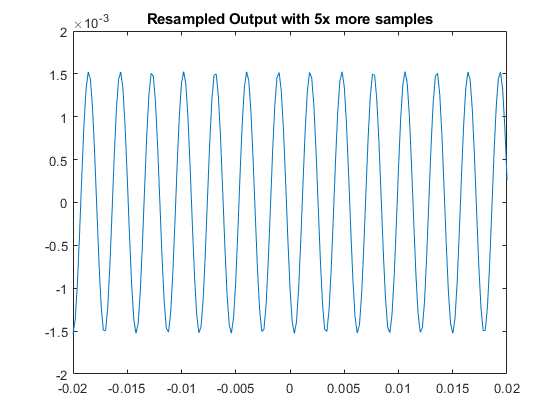

y2r = DSP_funcs.resampleSINC(y3n, resample_factor);
t = -10:Tr/resample_factor:10 + (resample_factor-1)*Tr/resample_factor;

plot(t, y2r)
xlim([-0.02, 0.02])
title("Resampled Output with 5x more samples")

As you can see in this last graph, with a 10x higher sampling frequency the output is now a -sin(t) signal instead of the sin(t) signal that you see at lower sample frequencies.